clear;
% A-1) Construct Legendre polynomials including P4(x) = x4 − 6/7 x2 + 3/35 (Gram-Schmidt)
% B-1) Construct Tchebyshev polynomials including T4(x) = 8x4 − 8x2 + 1. (Recurrence)

%Generate Legendre Polynomial
syms x
L= legendreP(4,x)

$$L = \frac{35\,x^{4}}{8}-\frac{15\,x^{2}}{4}+\frac{3}{8}$$

L= horner(L)

$$L = x^{2}\,\left(\frac{35\,x^{2}}{8}-\frac{15}{4}\right)+\frac{3}{8}$$

%Finds roots of L
Lroots = roots(sym2poly(L))

Lroots =    -0.8611
    0.8611
   -0.3400
    0.3400




% A-2) Set up and solve the equations for quadrature weights corresponding to the roots.
%Set up the quadrature nodes at each of the f(x) points
Quad = [ 1 1 1 1; Lroots(1) Lroots(2) Lroots(3) Lroots(4); Lroots(1)^2 Lroots(2)^2 Lroots(3)^2 Lroots(4)^2  ; Lroots(1)^3 Lroots(2)^3 Lroots(3)^3 Lroots(4)^3];
%Set each of the parts = to the integral between -1,1
ANS = [2; 0; 2/3; 0;];
%Solves for the w0 through w3
ANS = linsolve(Quad,ANS)

ANS =     0.3479
    0.3479
    0.6521
    0.6521


%Find the integral
Result = ANS(1)*Lroots(1) +ANS(1)*Lroots(2) +ANS(3)*Lroots(3) +ANS(4)*roots(4)


Result =

  0×1 empty double column vector



%A-3) Compare the accuracy of resulting formula and the trapezoidal rule on ∫  e^x dx.
syms x
Trapz = Trap(exp(x),0,1,4)

$$Trapz = \frac{\mathrm{e}}{8}+\frac{\sqrt{\mathrm{e}}}{4}+\frac{{\mathrm{e}}^{1/4}}{4}+\frac{{\mathrm{e}}^{3/4}}{4}+\frac{1}{8}$$

Error = (exp(1)-1)-Trapz

$$Error = \frac{3587751724472169}{2251799813685248}-\frac{\sqrt{\mathrm{e}}}{4}-\frac{{\mathrm{e}}^{1/4}}{4}-\frac{{\mathrm{e}}^{3/4}}{4}-\frac{\mathrm{e}}{8}$$


%The answer for A2 is 0 while A3 is -.76

%B)
T= chebyshevT(4,x)

$$T = 8\,x^{4}-8\,x^{2}+1$$

%Finds roots of T
Troots = roots(sym2poly(T))

Troots =    -0.9239
    0.9239
   -0.3827
    0.3827


Ty= [subs(T,x,Troots(1)) subs(T,x,Troots(2)) subs(T,x,Troots(3)) subs(T,x,Troots(4))];
%B-2) Implement divided difference interpolation
%I couldn't really get my divided difference code to work properly
coeffs = divided_diff([-2,0,1], [12,4,9]);
P = create_symbolic_polynomial([-2,0,1], coeffs);
disp(P);

$$3\,x^{2}+2\,x+4$$

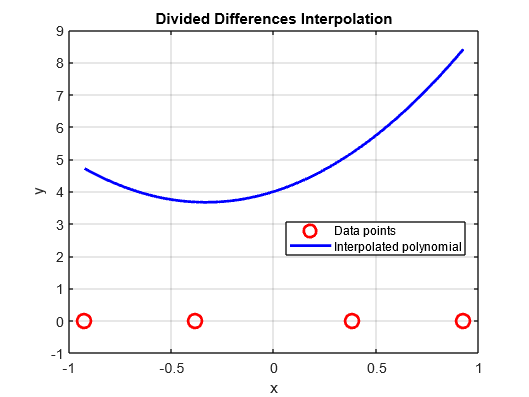



x_interp = linspace(min(Troots), max(Troots), 100);
y_interp = arrayfun(@(x_val) newton_interpolation([-2,0,1], [12,4,9], x_val), x_interp);


figure;
plot(Troots, Ty, 'ro', 'MarkerSize', 10, 'LineWidth', 2);
hold on;
plot(x_interp, y_interp, 'b-', 'LineWidth', 2);
xlabel('x');
ylabel('y');
title('Divided Differences Interpolation');
legend('Data points', 'Interpolated polynomial', 'Location', 'Best');
grid on;

%B3)
clear;
syms x
f= 1/(1+(5*x)^2)

$$f = \frac{1}{25\,x^{2}+1}$$

n=6;

%Equally space points
X=linspace(0,1,n);
Y= zeros(length(X),1);
for j=1: length(X)
    Y(j) = subs(f,x,X(j));
end
%At Tchebyschev roots
T= chebyshevT(n,x)

$$T = 32\,x^{6}-48\,x^{4}+18\,x^{2}-1$$

%Finds roots of T
Troots = roots(sym2poly(T))

Troots =    -0.9659
   -0.7071
    0.9659
    0.7071
   -0.2588
    0.2588


X2= Troots;
for j=1: length(X)
    Y2(j) = subs(f,x,X(j));
end

% Lagrange interpolation for Equally Space Points
P_lagrange = lagrange_interpolation(X, Y);

Li = 1

Li = 1

Li = 1

Li = 1

Li = 1

Li = 1

disp('Lagrange Interpolation:');

Lagrange Interpolation:


disp(P_lagrange)

$$\frac{625\,x\,\left(x-1\right)\,\left(x-\frac{1}{5}\right)\,\left(x-\frac{2}{5}\right)\,\left(x-\frac{4}{5}\right)}{24}-\frac{3125\,x\,\left(x-1\right)\,\left(x-\frac{1}{5}\right)\,\left(x-\frac{2}{5}\right)\,\left(x-\frac{3}{5}\right)}{408}-\frac{625\,x\,\left(x-1\right)\,\left(x-\frac{1}{5}\right)\,\left(x-\frac{3}{5}\right)\,\left(x-\frac{4}{5}\right)}{12}+\frac{3125\,x\,\left(x-1\right)\,\left(x-\frac{2}{5}\right)\,\left(x-\frac{3}{5}\right)\,\left(x-\frac{4}{5}\right)}{48}+\frac{625\,x\,\left(x-\frac{1}{5}\right)\,\left(x-\frac{2}{5}\right)\,\left(x-\frac{3}{5}\right)\,\left(x-\frac{4}{5}\right)}{624}-\frac{125\,\left(5\,x-1\right)\,\left(x-1\right)\,\left(x-\frac{2}{5}\right)\,\left(x-\frac{3}{5}\right)\,\left(x-\frac{4}{5}\right)}{24}$$

x_interp = linspace(min(X), max(X), 100);
y_newton_interp = arrayfun(@(x_val) newton_interpolation(X, Y, x_val), x_interp);
y_lagrange_interp = double(subs(P_lagrange, x_interp));
plot(x_interp, y_lagrange_interp, 'b--', 'LineWidth', 2);
% Lagrange interpolation
P_lagrange = lagrange_interpolation(X2, Y2);

Li = 1

Li = 1

Li = 1

Li = 1

Li = 1

Li = 1

disp('Lagrange Interpolation:');

Lagrange Interpolation:


disp(P_lagrange)

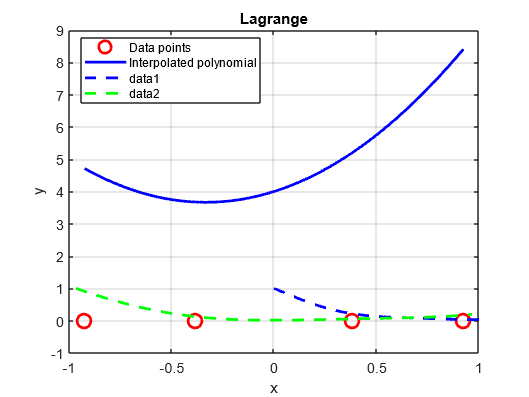


x_interp = linspace(min(X2), max(X2), 100);
y_lagrange_interp = double(subs(P_lagrange, x_interp));
plot(x_interp, y_lagrange_interp, 'g--', 'LineWidth', 2);

xlabel('x');
ylabel('y');
title('Lagrange');

%I could't get this plot to work very well

function [L] = lagrange_interpolation(X, y)
    n = length(X);
    syms x;
    L = 0;

    for i = 1:n
        Li = 1
        for j = 1:n
            if i ~= j
                Li = Li * (x - X(j)) / (X(i) - X(j));
            end
        end
        L = L + y(i) * Li;
    end

    % L = simplify(L);
end
function [coeffs] = divided_diff(x, y)
    n = length(x);
    divided_diff_table = zeros(n);
    divided_diff_table(:,1) = y';

    for j = 2:n
        for i = 1:(n-j+1)
            divided_diff_table(i, j) = (divided_diff_table(i+1, j-1) - divided_diff_table(i, j-1)) / (x(i+j-1) - x(i));
        end
    end

    coeffs = divided_diff_table(1, :);
end

function [y_interp] = newton_interpolation(x, y, x_interp)
    coeffs = divided_diff(x, y);
    n = length(coeffs);
    y_interp = coeffs(n);

    for i = n-1:-1:1
        y_interp = y_interp * (x_interp - x(i)) + coeffs(i);
    end
end

function [P] = create_symbolic_polynomial(X, coeffs)
    syms x;
    n = length(coeffs);
    P = coeffs(1);

    for i = 2:n
        term = 1;
        for j = 1:i-1
            term = term * (x - X(j));
        end
        P = P + coeffs(i) * term;
    end
    P = simplify(P);
end


function y=lagrange(pointx,pointy)
 syms x
 y=0;
for i = 1: length(pointx)
 y=y+ pointy(i)*(denom(pointx(i),pointx)/numer(pointx(i),pointx));
end
 end

 function n= numer(a,pointx)
 for i= 1:length(pointx)
   m(i) = a-pointx(i);
   if m==0
       m=1;
   end
   
 end
 n= dot(m,1:1:length(pointx));
 end

 function d= denom(a,pointx)
syms x
d=1;
 for i= 1:length(pointx)
  if pointx(i) ==a
      m=1;
  else
  m= (x- pointx(i));
  end
  d=d*m;
 end

 end
function  Trap =  Trap(f,a,b,n)
 syms x
 h=(b-a)/n;
 s0=subs(f,x,a)+subs(f,x,b);
 s1=0;
 for i=1:n-1
    x1=a+i*h;
    s1=s1+subs(f,x,x1);
 end
 s=(h/2)*(s0+2*s1);
Trap =s;
end